Convert VG to GD(Gardner model)

plot VG in descrete space.

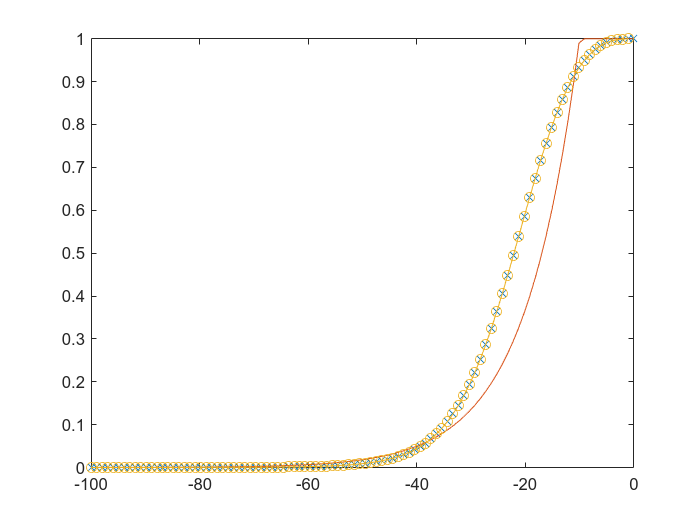

clear;
psi = linspace(-100,0,100);

%------------VG MODEL
theta_s = 0.6;
theta_r = 0.01;

av = 0.03; %unit cm^-1 for sand 0.0324, clay 0.0066
n = 3.86; % for sand 6.66, clay 1.86 
m = 1 - 1/n;

THET = (1 + (av*(abs(psi))).^n).^(-m);
% THET = (theta - theta_r)/(theta_s - theta_r)
theta = theta_r + THET*(theta_s - theta_r);
kr_vg = THET.^0.5.*(1 - (1 - THET.^(1/m)).^m).^2;


%----------GD Model
ag = 0.1;
psi_b = -10;

kr_gd = ones(size(psi));
kr_gd(psi < psi_b) = exp(ag*(psi(psi < psi_b) - psi_b));


% ----linear descrete GD model
blc = linspace(-100,0,100);

THET_blc = (1 + (av*(abs(blc))).^n).^(-m);
kr_blc = THET_blc.^0.5.*(1 - (1 - THET_blc.^(1/m)).^m).^2;
%blc = linspace(-100,0,2); % divide psi into blocks

ag_fit = log(kr_blc)./blc;
kr_fit = exp(ag_fit.*blc);

 

figure;
plot(psi,kr_vg,'x-',psi,kr_gd,blc,kr_fit,'-o')

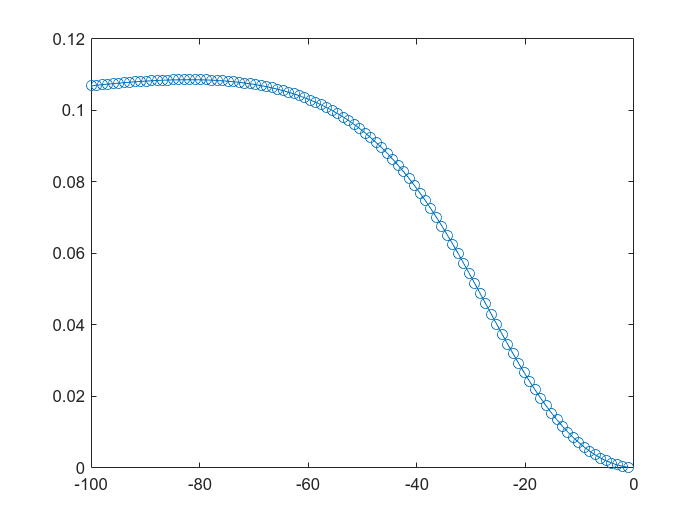


figure;
plot(blc,ag_fit,'o-')


RMSE = sqrt(sum((kr_gd - kr_vg).^2)/numel(psi))

RMSE = 0.0757

RMSE2 = sum(abs((kr_gd - kr_vg)/kr_vg))

RMSE2 = 0.0896

Test fun_vg2gd.m

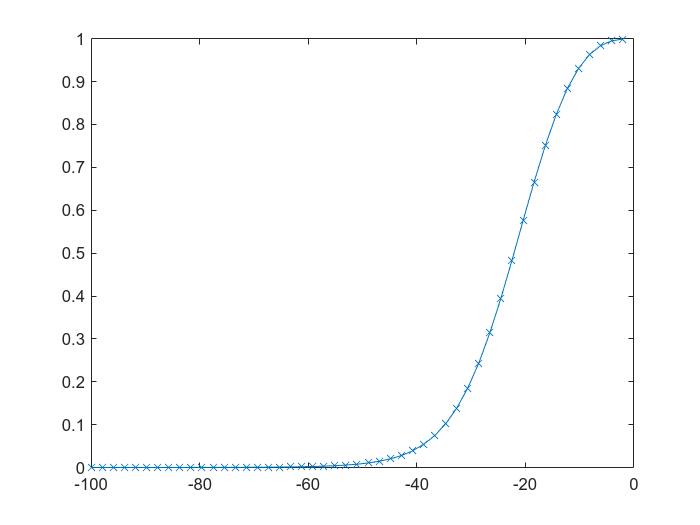

psi2 = linspace(-100,0,50);
ag_fun=zeros(size(psi2));
th_fun=zeros(size(psi2));
kr_fun=zeros(size(psi2));


for i = 1:numel(psi2)
    [ag_fun(i),th_fun(i),kr_fun(i),~] = fun_vg2gd(av,n,theta_s,theta_r,psi2(i));
end


figure;
plot(psi2,kr_fun,'x-')

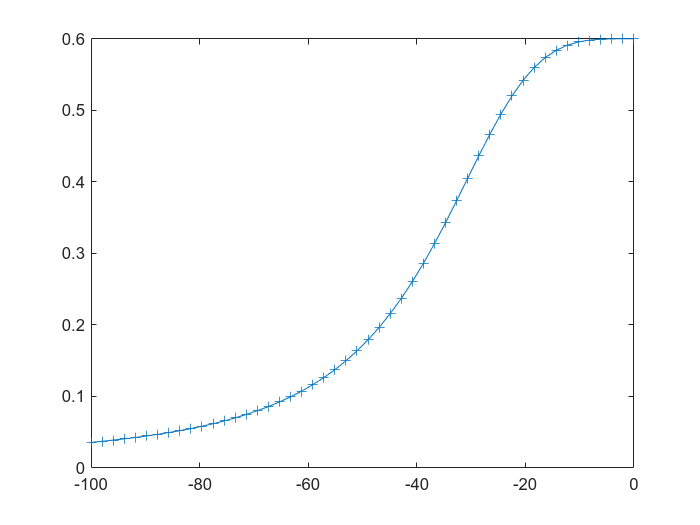


figure;
plot(psi2,th_fun,'+-')

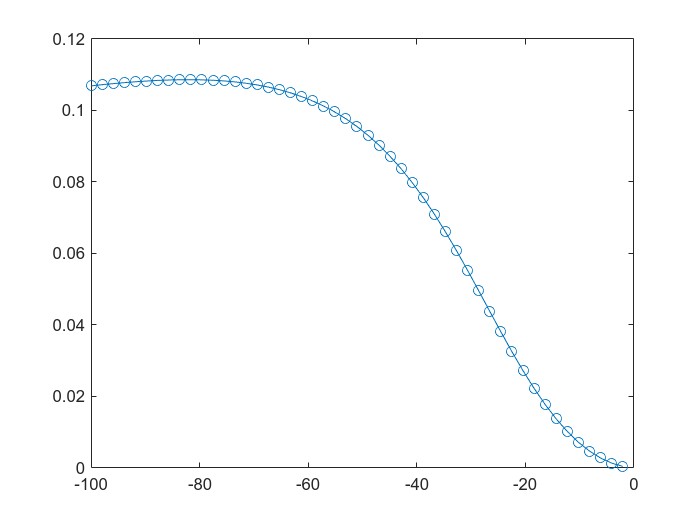


figure;
plot(psi2,ag_fun,'o-')

## verification

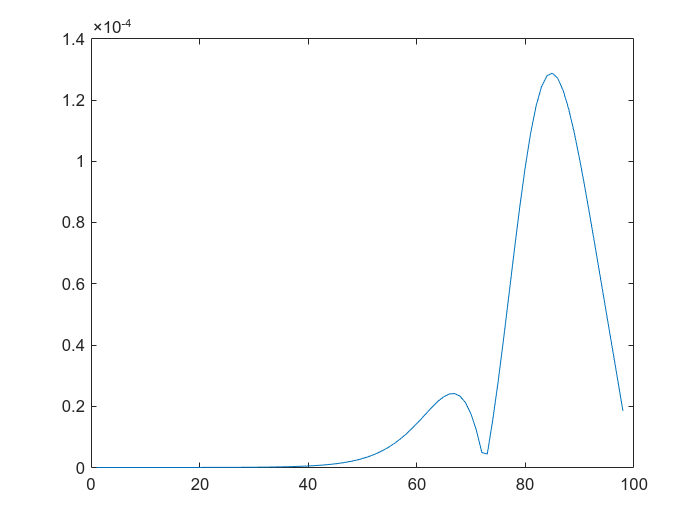

ns = 100; %number of slices for psi
nss = 10; %number of sub-slices for one slice of psi (for verification)

psi3 = linspace(-100,0,ns);
sub_psi3 = zeros(ns-1,nss);
rmse3 = zeros(ns-1,1);
rmse4 = zeros(ns-1,1);

for j = 1:ns-1
    % devide sub-block of psi2
    sub_psi3(j,:) = linspace(psi3(j),psi3(j+1),nss);
    ag_ver = zeros(nss,1);
    kr_ver = zeros(nss,1);
    ag_intpol = zeros(nss,1);
    kr_intpol = zeros(nss,1);

    for i = 1:nss
        [ag_ver(i),~,~,kr_ver(i)] = fun_vg2gd(av,n,theta_s,theta_r,sub_psi3(j,i));
    end
    
    for i = 1:nss
        ag_intpol(i) = ag_ver(1) + (i-1)*(ag_ver(end) - ag_ver(1))/(nss-1);
        kr_intpol(i) = exp(ag_intpol(i)*sub_psi3(j,i));
    end
    
    rmse3(j) = sqrt(sum((kr_intpol - kr_ver).^2)/nss);
    %rmse4(j) = sum(abs((kr_intpol - kr_ver)./kr_ver));
end

figure;
plot (1:ns-1,rmse3)

more verification : effect of nslice on error


%avg_rmse4 = zeros(100,1);
avg_rmse3 = zeros(100,1);

parfor k = 1:1000
    ns = k*200; %number of slices for psi
    nss = 10; %number of sub-slices for one slice of psi (for verification)
    
    psi3 = linspace(-100,0,ns);    
    sub_psi3 = zeros(ns-1,nss);
    rmse3 = zeros(ns-1,1);
    %rmse4 = zeros(ns-1,1);
    
    for j = 1:ns-1
        % devide sub-block of psi2
        sub_psi3(j,:) = linspace(psi3(j),psi3(j+1),nss);
        ag_ver = zeros(nss,1);
        kr_ver = zeros(nss,1);
        ag_intpol = zeros(nss,1);
        kr_intpol = zeros(nss,1);
    
        for i = 1:nss
            [ag_ver(i),~,~,kr_ver(i)] = fun_vg2gd(av,n,theta_s,theta_r,sub_psi3(j,i));
        end
        
        for i = 1:nss
            ag_intpol(i) = ag_ver(1) + (i-1)*(ag_ver(end) - ag_ver(1))/(nss-1);
            kr_intpol(i) = exp(ag_intpol(i)*sub_psi3(j,i));
        end
        
        rmse3(j) = sqrt(sum((kr_intpol - kr_ver).^2)/nss);
        %rmse4(j) = sum(abs((kr_intpol - kr_ver)./kr_ver));
    end

    avg_rmse3(k) = mean(rmse3(1:end-1));
    %avg_rmse4(k) = mean(rmse4);
end



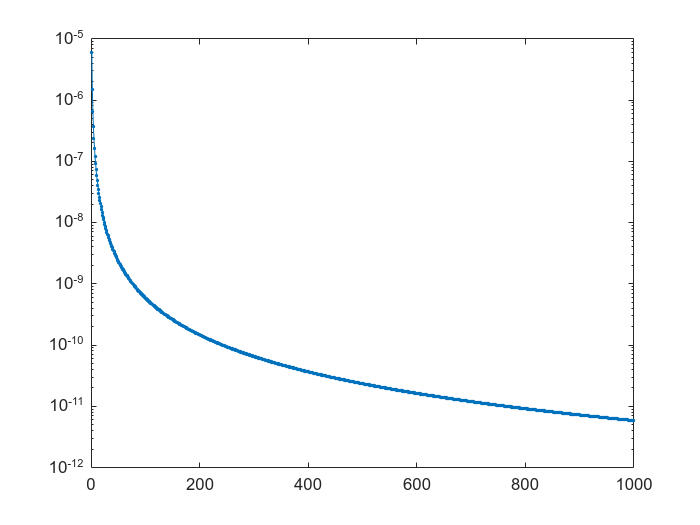

figure;
plot(avg_rmse3,'.-')
set(gca, 'YScale', 'log')